# Credit Scorecard Development

## Scope

ModelName = 'Refaat 2011 Credit Card Model';
ModelVersion = '1.0';
ModelStatus = 'Draft';
Title = 'Refaat 2011 Credit Card Model';
Subject = 'Model Development Documentation';
%comentario

**Load the Data from Refaat 2011**

Load dataset from Refaat 2011

whos -file CreditCardData

  Name             Size            Bytes  Class    Attributes

  data              -              84604  table              
  dataMissing       -              84604  table              
  dataWeights       -              94432  table              



load CreditCardData.mat

Standardize variable names

data.Properties.VariableNames{'CustID'} = 'IDVar';
data.Properties.VariableNames{'status'} = 'ResponseVar';
dataMissing.Properties.VariableNames{'CustID'} = 'IDVar';
dataMissing.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'CustID'} = 'IDVar';
dataWeights.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'RowWeights'} = 'WeightsVar';

filteredData = dataMissing;
filteredData(:,'CustAge') = [];% #1 sensitive variable

summary(dataMissing(:,'CustAge'))

Description:  Credit card dataset, from: M. Refaat, Credit Risk Scorecards, lulu.com, 2011.

Variables:

    CustAge: 1200×1 double

        Values:

            Min              21   
            Median           45   
            Max              74   
            NumMissing       30   



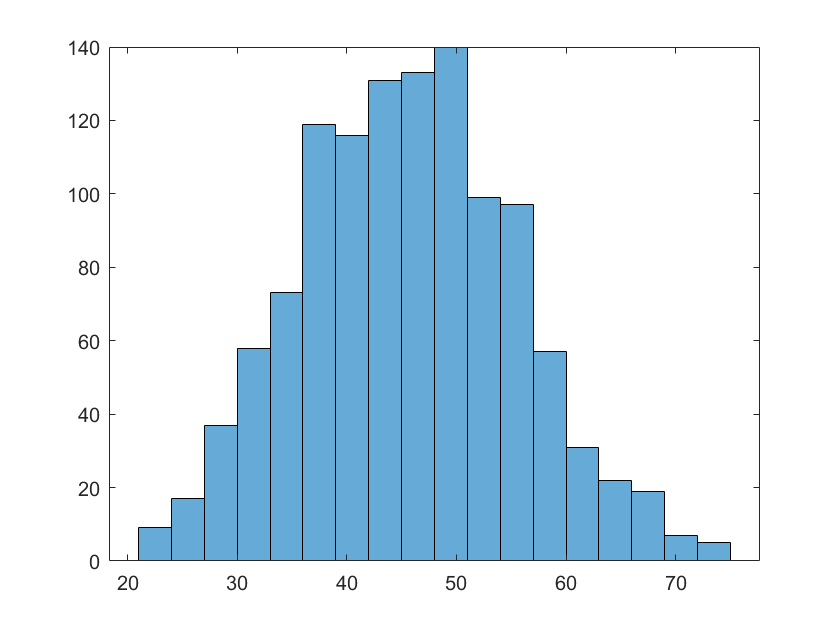

histogram(dataMissing{:,'CustAge'})